% Example_5_4.mlx
%
% This is Example 5.4 from the paper 'Laguerre tessellations and 
% polycrystalline microstructures: A fast algorithm for generating grains 
% of given volumes' by D.P. Bourne, P.J.J. Kok, S.M. Roper, W.D.T. Spanjer
% (Philosophical Magazine 100, 2677-2707, 2020).
%
% We generate a 3D periodic Laguerre diagram representing an idealised 
% DP (dual phase) steel in which the two phases are arranged in layers.

clear

tic

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Specify whether the Laguerre diagram is periodic (periodic=true) or
% non-periodic (periodic=false)

periodic=true; 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Define the geometry. We create a 3D periodic Laguerre diagram in a 
% rectangular box with vertices (0,0,0), (L1,0,0), (0,L2,0), (0,0,L3), 
% (L1,L2,0), (L1,0,L3), (0,L2,L3), (L1,L2,L3).

L1=2; % length of the box in the x-direction
L2=3; % length of the box in the y-direction
L3=2; % length of the box in the z-direction
bx=[L1,L2,L3];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Specify the desired volumes of the grains. These are stored in a column
% vector called target_vols.

NumLayers=3; % number of layers
nLayer=[1000;8000;1000]; % number of grains per layer
rLayer=[1;0.05;1]; % size ratio of the grains per layer

N=sum(nLayer); % total number of grains
target_vols=zeros(N,1);
for j=1:NumLayers
    target_vols(sum(nLayer(1:j-1))+1:sum(nLayer(1:j-1))+nLayer(j))=...
        rLayer(j);
end

% Normalise the volumes so that they add to the volume of the box
target_vols = target_vols*L1*L2*L3/sum(target_vols); 

% Set the phase ID to correspond to the grain size.
% The large grains have phaseID=1, the small grains have phaseID=2.
phaseID=ones(size(target_vols)); 
phaseID(nLayer(1)+1:nLayer(1)+nLayer(2))=2;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Choose the optimisation solver

solver='dampedNewton'; % damped Newton method (recommended)
% solver='fminunc'; % slower option

% Remark:
% In the paper 'Laguerre tessellations and polycrystalline microstructures:
% A fast algorithm for generating grains of given volumes' by D.P. Bourne, 
% P.J.J. Kok, S.M. Roper, W.D.T. Spanjer (2020), we used the MATLAB solver
% fminunc. A faster option is to use the damped Newton method, as 
% described in 'Geometric modelling of polycrystalline materials: Laguerre 
% tessellations and periodic semi-discrete optimal transport' by 
% D.P. Bourne, M. Pearce & S.M. Roper (2022).

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Initialise the seed locations

% Choose the x- and y-coordinates of the initial seed locations randomly
x0=L1*rand(N,1);
y0=L2*rand(N,1);

% Define the z-coordinates of the initial seed locations by placing the 
% seeds in layers
vLayer=zeros(NumLayers,1); % desired volume of grains per layer
for  j=1:NumLayers
    vLayer(j)=...
        sum(target_vols(sum(nLayer(1:j-1))+1:sum(nLayer(1:j-1))+nLayer(j)));
end
tLayer=vLayer/L1/L2; % desired thickness of each layer 
z0=zeros(N,1);
for j=1:NumLayers
    z0(sum(nLayer(1:j-1))+1:sum(nLayer(1:j-1))+nLayer(j))=...
        tLayer(j)*rand(nLayer(j),1)+sum(tLayer(1:j-1));
end

X0=[x0,y0,z0]; % initial location of the seeds

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Perform Algorithm 2 from the paper 'Laguerre tessellations and 
% polycrystalline microstructures: A fast algorithm for 
% generating grains of given volumes' by D.P. Bourne, P.J.J. Kok, 
% S.M. Roper, W.D.T. Spanjer (Philosophical Magazine 100, 2677-2707, 2020).

% Set the parameters of the algorithm
numLloyd=20; % number of regularisation (Lloyd) iterations
tol=1; % percentage error tolerance for the volumes of the grains

% Perform Algorithm 2
[X,w,percent_error,actual_vols]=...
    algorithm2(bx,X0,target_vols,periodic,tol,numLloyd,solver);

Lloyd iteration:1
Lloyd iteration:2


Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5
Lloyd iteration:6
Lloyd iteration:7
Lloyd iteration:8
Lloyd iteration:9
Lloyd iteration:10
Lloyd iteration:11
Lloyd iteration:12
Lloyd iteration:13
Lloyd iteration:14
Lloyd iteration:15
Lloyd iteration:16
Lloyd iteration:17
Lloyd iteration:18
Lloyd iteration:19
Lloyd iteration:20



% Output the difference (percentage error) between the actual volumes of 
% the grains and the target volumes 
disp(strcat('Maximum percentage error=',num2str(percent_error),'%'));

Maximum percentage error=0.15197%



toc

Elapsed time is 168.555262 seconds.


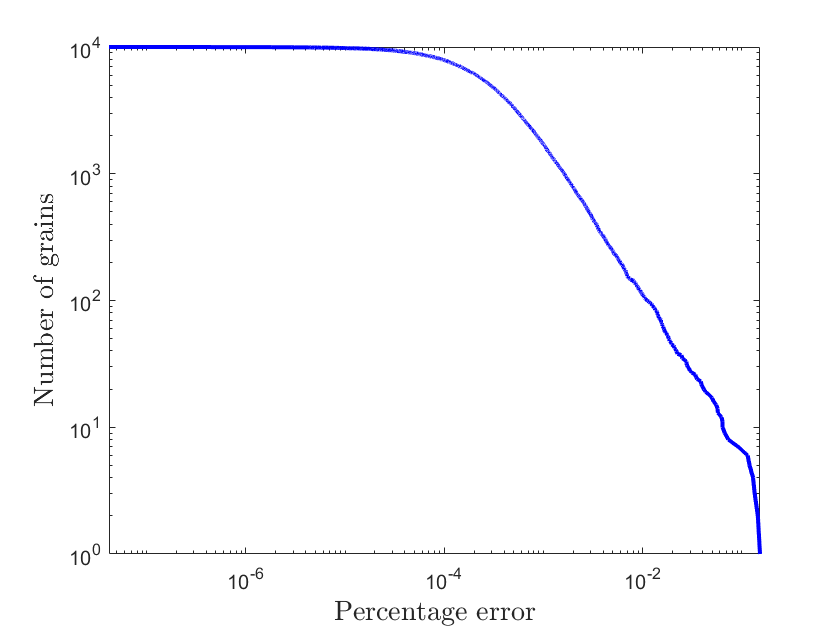


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Save the results in a txt file

x=X(:,1);
y=X(:,2);
z=X(:,3);
fileID = fopen('Weight_data_Example_5_4.txt','w');
fprintf(fileID,'%06d %5.3f  %5.3f  %5.3f  %u \r\n',length(x),L1,L2,L3,int8(periodic));
for i=1:length(x)
    fprintf(fileID,'%06d %-3.7e %-3.7e %-3.7e %-3.7e %3.1f\r\n',...
        [i,w(i),x(i),y(i),z(i),phaseID(i)]);
end
fclose(fileID);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Plot the volume errors

percentage_errors=100*abs(actual_vols-target_vols)./target_vols;
plotErrors(percentage_errors);

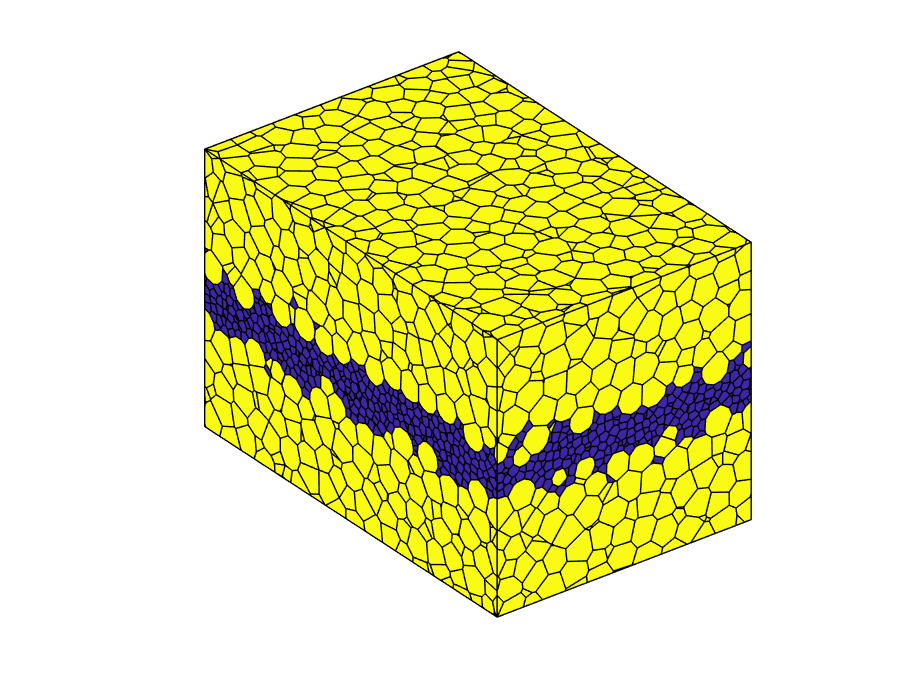

drawnow

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Plot the Laguerre tessellation

% Compute the vertices, faces, neighbours (vfn) of the Laguerre diagram
[~,~,~,vfn]=mexPDall(bx,X,w,periodic); 

% Compute which cells lie on the boundary of the box (no need to plot the 
% interior cells since they are not visible)
[polys,cellids]=intersect_cells_on_boundary_periodic(bx,vfn);

% Colour the grains according to their volume, using a log scale
colormap=parula;
myc=generateGrainColours(log(actual_vols));

% Plot the Laguerre tessellation
figure
patchpolygons(polys,cellids,myc);
view([-37.5,30])
axis equal
axis off